# 距离徙动

距离徙动的分量：


$$R(\eta)=R(\eta_c)+\frac{V_r^2\eta_c}{R(\eta_c)}(\eta-\eta_c)+\frac{1}{2}\frac{V_r^2\cos^2\theta_{r,c}}{R(\eta_c)}(\eta-\eta_c)^2$$


        
$$=R(\eta_c)-V_r\sin\theta(\eta-\eta_c)+\frac{1}{2}\frac{V_r^2\cos^2\theta_{r,c}}{R(\eta_c)}(\eta-\eta_c)^2$$


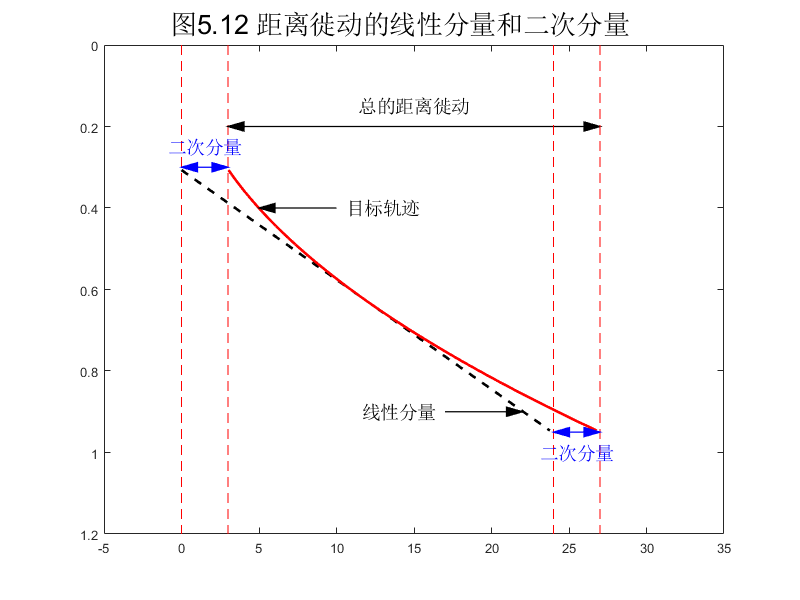

clc
clear
close all
% 已知参数--》距离向参数
R_eta_c = 850e+3;                       % 景中心斜距
% 已知参数--》方位向参数
Vr = 7100;                              % 等效雷达速度
Ta = 0.64;                              % 目标照射时间
Ka = 2095;                              % 方位向调频率
theta_r_c = -0.3*pi/180;                % 斜视角
% 参数计算
Delta_f_dop = abs(Ka*Ta);               % 方位信号带宽
eta_c = -R_eta_c*sin(theta_r_c)/Vr;     % 波束中心穿越时刻
% 参数设置
alpha_a_s = 1;                          % 方位过采样率
Fa = alpha_a_s*Delta_f_dop;             % 方位采样频率PRF
N = 2*ceil(Fa*Ta/2);                    % 方位采样点数
dt = Ta/N;                              % 采样时间间隔
df = Fa/N;                              % 采样频率间隔 
% 变量设置
eta =  (-Ta/2:dt:Ta/2-dt) + eta_c;      % 方位时间变量
% 信号表达
R_eta = R_eta_c -...
        Vr*sin(theta_r_c)*(eta-eta_c) +...
        (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(eta-eta_c).^2;       % 瞬时斜距展开式
%{
R_eta = sqrt(R0^2 + Vr^2*eta^2) % 瞬时斜距的双曲线形式                        
R_eta = R0 + Vr^2*eta^2/(2*R0)  % 瞬时斜距的抛物线形式                
R_eta = R_eta_c -...
        Vr^2*eta_c/R_eta_c*(eta-eta_c) +...
        (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(eta-eta_c).^2;
R_eta = R_eta_c -...
        Vr*sin(theta_r_c)*(eta-eta_c) +...
        (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(eta-eta_c).^2;
%}
RCM_1 = -Vr*sin(theta_r_c)*(eta-eta_c+Ta/2);                         % 距离徙动线性分量
RCM_2 = (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(eta-eta_c).^2;        % 距离徙动二次分量
RCM_all = RCM_1 + RCM_2;                                             % 距离徙动总量
% 绘图                                                                
H = figure();
set(H,'position',[100,100,800,600]);
plot(RCM_1,eta,'k--','LineWidth',2),set(gca,'ydir','reverse'),hold on
plot(RCM_all,eta,'r','LineWidth',2)
axis([-5 35 0 1.2])
line([0,0],[0,1.2],'Color','r','LineStyle','--')
line([3,3],[0,1.2],'Color','r','LineStyle','--')
arrow([3,0.2],[27,0.2],'Color','k','Linewidth',1);
arrow([27,0.2],[3,0.2],'Color','k','Linewidth',1);
text(15,0.15,'总的距离徙动','FontSize',14,'Color','black','HorizontalAlignment','center')
arrow([0,0.3],[3,0.3],'Color','b','Linewidth',1);
arrow([3,0.3],[0,0.3],'Color','b','Linewidth',1);
text(1.5,0.25,'二次分量','FontSize',14,'Color','blue','HorizontalAlignment','center')
line([24,24],[0,1.2],'Color','r','LineStyle','--')
line([27,27],[0,1.2],'Color','r','LineStyle','--')
arrow([24,0.95],[27,0.95],'Color','b','Linewidth',1);
arrow([27,0.95],[24,0.95],'Color','b','Linewidth',1);
text(25.5,1,'二次分量','FontSize',14,'Color','blue','HorizontalAlignment','center')
arrow([10,0.4],[5,0.4],'Color','k','Linewidth',1);
text(13,0.4,'目标轨迹','FontSize',14,'Color','black','HorizontalAlignment','center')
arrow([17,0.9],[22,0.9],'Color','k','Linewidth',1);
text(14,0.9,'线性分量','FontSize',14,'Color','black','HorizontalAlignment','center')
sgtitle('图5.12 距离徙动的线性分量和二次分量','Fontsize',20,'color','k')

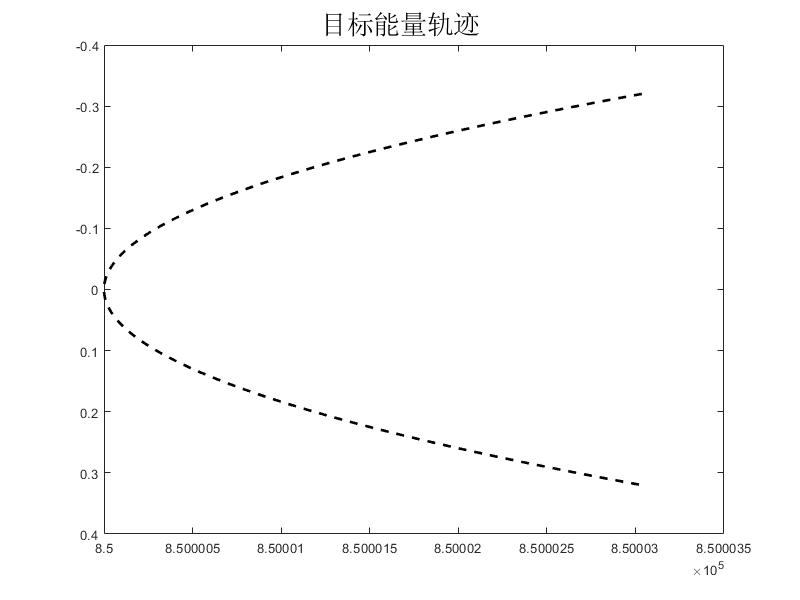

clc
clear
close all
% 已知参数--》距离向参数
R_eta_c = 850e+3;                       % 景中心斜距
% 已知参数--》方位向参数
Vr = 7100;                              % 等效雷达速度
Ta = 0.64;                              % 目标照射时间
Ka = 2095;                              % 方位向调频率
theta_r_c = 0*pi/180;     % 斜视角
% 参数计算
Delta_f_dop = abs(Ka*Ta);               % 方位信号带宽
eta_c = -R_eta_c*sin(theta_r_c)/Vr;% 波束中心穿越时刻
% 参数设置
alpha_a_s = 1;                          % 方位过采样率
Fa = alpha_a_s*Delta_f_dop;             % 方位采样频率PRF
N = 2*ceil(Fa*Ta/2);                    % 方位采样点数
dt = Ta/N;                              % 采样时间间隔
df = Fa/N;                              % 采样频率间隔 
% 变量设置
eta =  (-Ta/2:dt:Ta/2-dt) + eta_c;      % 方位时间变量
% 信号表达
R_eta = R_eta_c -...
        Vr*sin(theta_r_c)*(eta-eta_c+Ta/2) +...
        (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(eta-eta_c).^2;      % 瞬时斜距展开式
RCM_1 = -Vr*sin(theta_r_c)*(eta-eta_c+Ta/2);                       % 距离徙动线性分量
RCM_2 = (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(eta-eta_c).^2;      % 距离徙动二次分量
RCM_all = RCM_1 + RCM_2;                                           % 距离徙动总量
% 绘图                                                                
G = figure();                                                           
set(G,'position',[100,100,800,600]);
plot(R_eta,eta,'k--','LineWidth',2);set(gca,'ydir','reverse')
sgtitle('目标能量轨迹','Fontsize',20,'color','k')

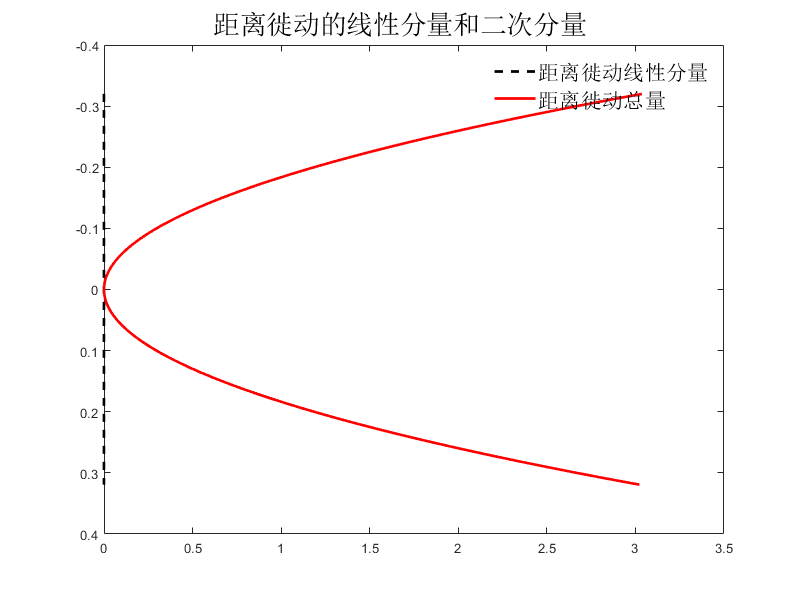

% 绘图                                                                
H = figure();                                                           
set(H,'position',[100,100,800,600]);
p1 = plot(RCM_1,eta,'k--','LineWidth',2);set(gca,'ydir','reverse'),hold on
p2 = plot(RCM_all,eta,'r','LineWidth',2);
sgtitle('距离徙动的线性分量和二次分量','Fontsize',20,'color','k')
% 图例
legend('boxoff');
lgd = legend([p1,p2],{'距离徙动线性分量','距离徙动总量'},'FontSize',16,'TextColor','k','Location','NorthEast','NumColumns',1);

可见，在小斜视角情况下，总的距离徙动主要由二次分量构成；在打斜视角情况下，总的距离徙动主要由线性分量构成。